Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


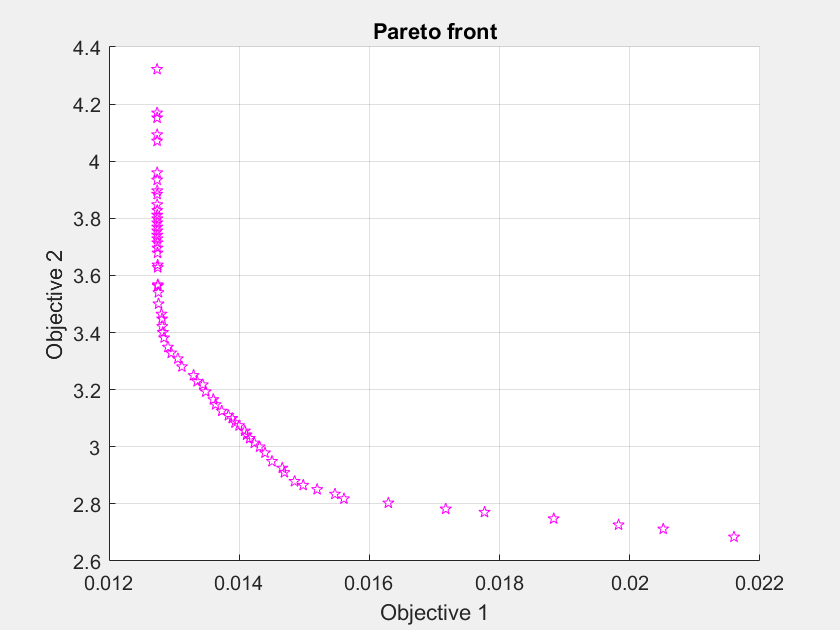

% Set nondefault solver options
options = optimoptions('gamultiobj','PopulationSize',70,'ParetoFraction',0.7,...
    'PlotFcn','gaplotpareto');

% Solve
[solution,objectiveValue] = gamultiobj(@multi,nvar,a,b,[],[],lb,ub,@nonlcon,...
    options);


% Clear variables
clearvars options

nvar=4;
lb=[55 75 1000 2];
ub=[80 110 3000 20];
a=[1 -1 0 0;0 0 0 1];
b=[-20;11];

function f=multi(x)
 f(1) = 4.9*10^(-5)*((x(2)^2-x(1)^2)/(x(4)-1)) ;
 f(2) = 9.82*10^6*(x(2)^2-x(1)^2)/(x(3)*x(4)*(x(2)^3 - x(1)^3));
end
function [c,ceq]= nonlcon(x)
 g1= (x(3)/(3.14*(x(2)^2-x(1)^2)^2))-0.4;
 g2= ((2.22*10^(-3)*x(3)*(x(2)^3-x(1)^3))/((x(2)^2-x(1)^2)^2)) - 1;
 g3= 900 - ((2.66*10^(-2)*x(3)*x(4)*(x(2)^3-x(1)^3))/(x(2)^2-x(1)^2));
 c=[g1,g2,g3];
 ceq=[];
end